# Customizable Assignment Report: Calculate Assignment Scores for each Learner from MATLAB Grader Assignment Report

Copyright 2021 The MathWorks, Inc

This script shows how to create a Customizable Assignment Report, that is a list of students with the number of problems they saved correctly or the mean percentage score they received for problems, from the Assignment Report generated in MATLAB Grader. It refers to the hosted version of MATLAB Grader at [grader.mathworks.com](https://grader.mathworks.com/).

## Get the report 

You can generate an Assignment Report for each assignment in a MATLAB Grader course at [grader.mathworks.com](https://grader.mathworks.com/).

- Navigate to the assignment for which you would like to generate a report. Reports can only be generated from the assignment level.

- In the right hand corner click "Actions" and choose "Report".

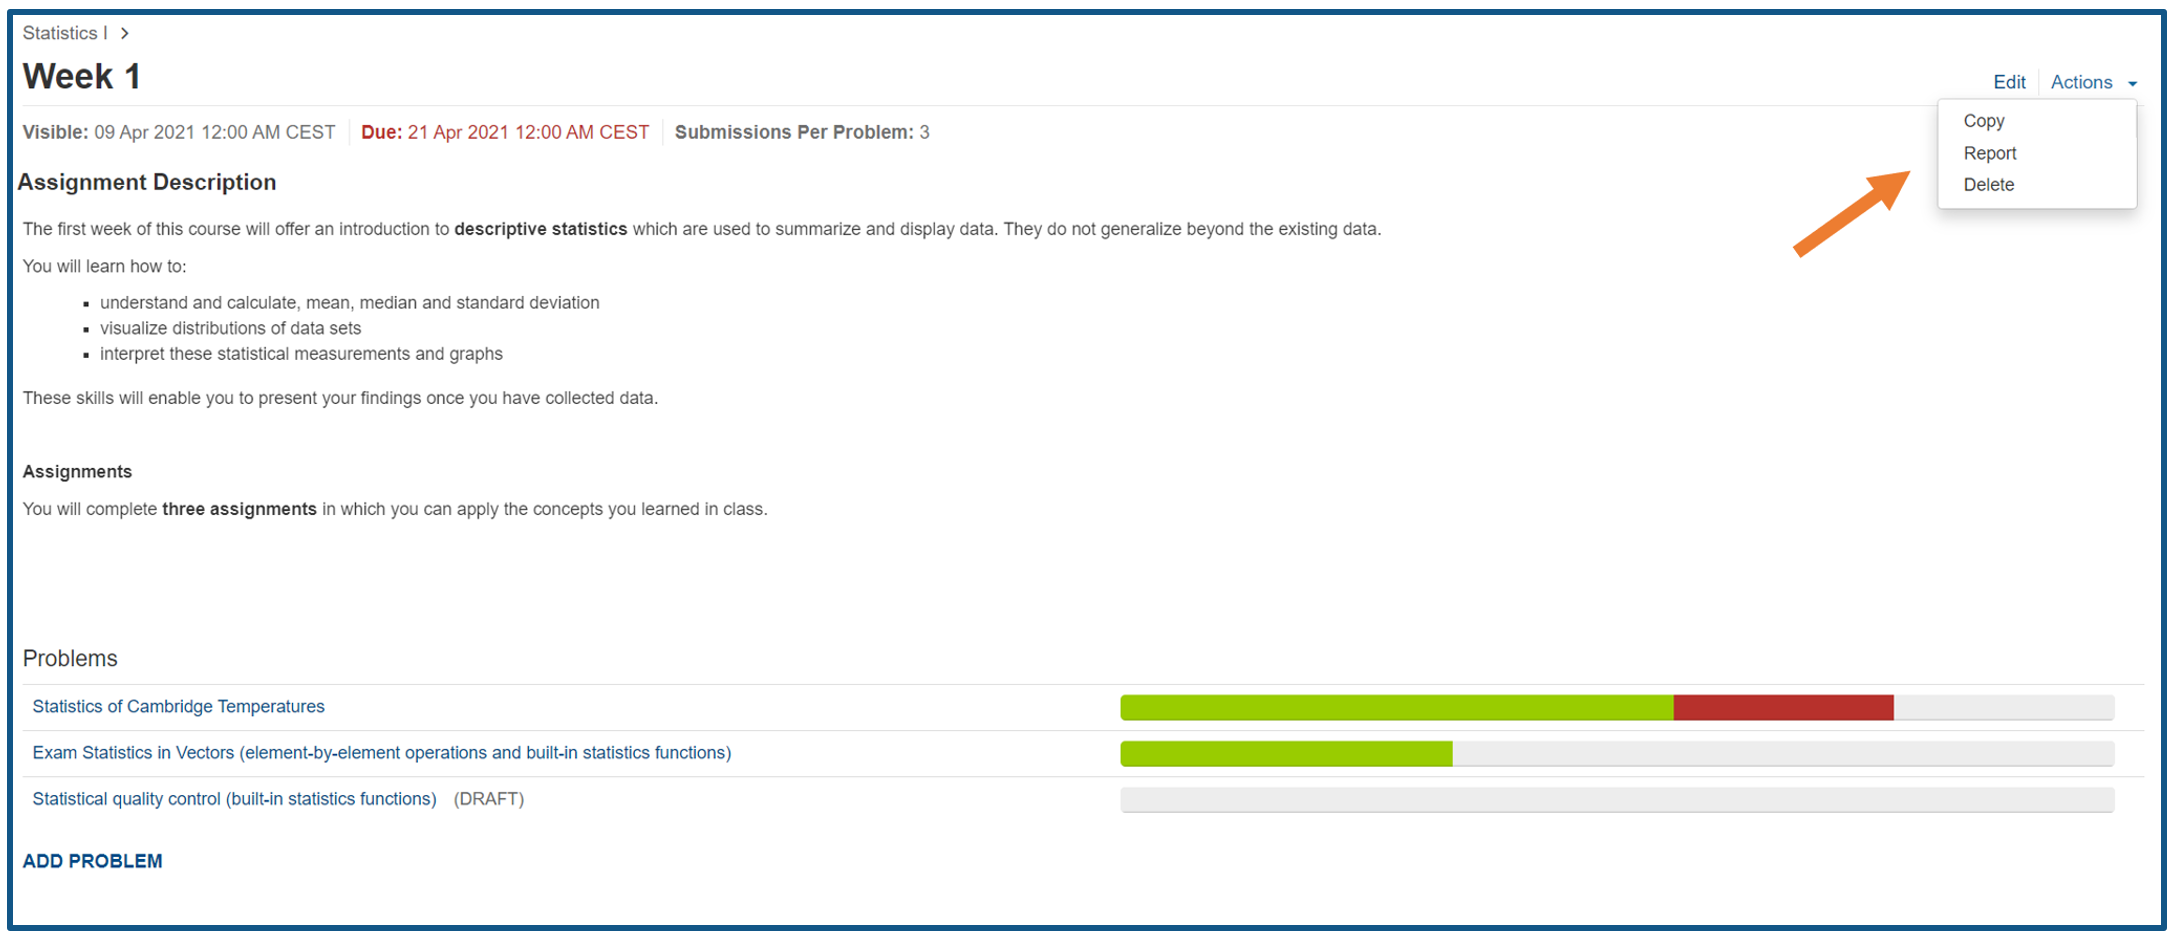

- For a grade book choose either "Best solutions as of due date" to only see the solutions submitted by the due date or "Best solution as of today" to also include late submissions. Choose "Excel" as output format.

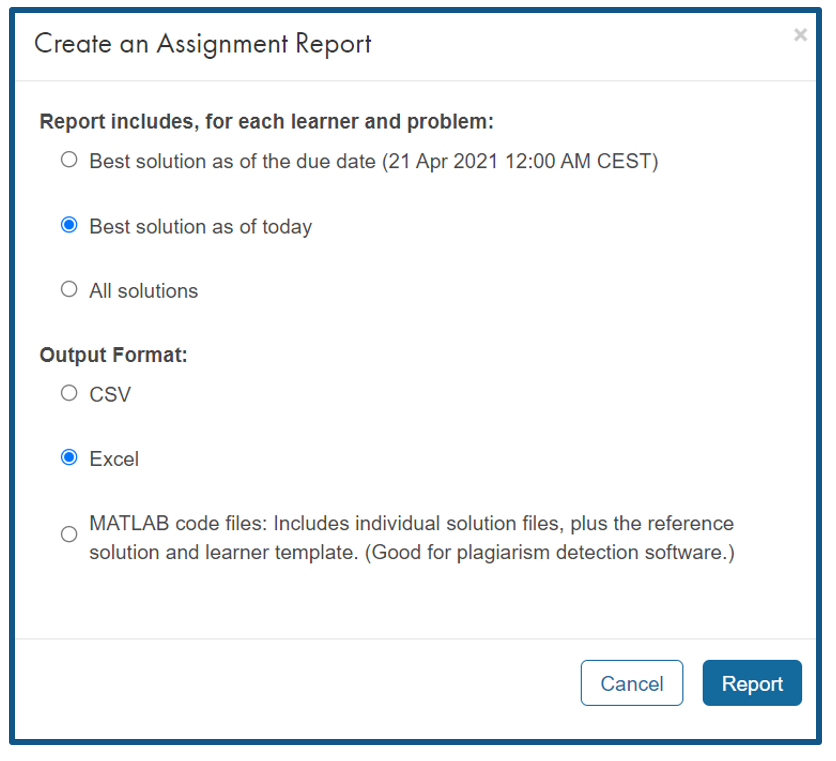

## Create Customizable Assignment Report

#### Load report into MATLAB

report = readtable(fullfile(pwd,'example_week.xlsx'));

You will receive a warning that says "Column headers from the file were modified to make them valid MATLAB identifiers." This means column headers like "Student Name" were changed to "StudentName". Display the first 10 rows of the report and the columns 'StudentName', 'AssignmentTitle', 'ProblemTitle', 'Correct', 'x_Score' and 'LateSubmission_':

disp(report(1:10, {'StudentName', 'AssignmentTitle', 'ProblemTitle', 'Correct', 'x_Score', 'LateSubmission_'}))

     StudentName     AssignmentTitle                                              ProblemTitle                                              Correct    x_Score     LateSubmission_
    _____________    _______________    ________________________________________________________________________________________________    _______    ________    _______________

    {'Sebastian'}      {'Week 1'}       {'Statistics of Cambridge Temperatures'                                                        }       0       {'0%'  }         {'N'}     
    {'Jeff'     }      {'Week 1'}       {'Statistics of Cambridge Temperatures'                                                        }       0       {'0%'  }         {'N'}     
    {'Steve'    }      {'Week 1'}       {'Statistics of Cambridge Temperatures'

Get all column headers:

columnHeaders = report.Properties.VariableNames;

**Set number of problems in assigment**

This is the number of problems in the assignment to check whether students solved all problems. You can either determine the number of problems automatically or set it manually. The automatic detection will only count those problems that were attempted by at least one student as only those are in the excel sheet.

numProblems_autoDetermined=numel(unique(report.ProblemID))

numProblems_autoDetermined = 2

numProblems = 2; % the report example_week.xlsx has two problems

Alternatively, you may set the number of problems needed to pass the assignment. For example, if an assignment has 5 problems and you want students to pass when they solved three or more problems correctly you may set numProblems to 3.

#### Get number of problems the students solved correctly

The column "Correct" shows a "1" if the student solved the problem correctly and a "0" otherwise. Adding the values in the "Correct" column for each students gives a table that can be used as gradebook. "Group Count" shows how often a student name was in the table. "sum_Correct" gives the sum of the values in "Correct". If this sum equals the number of assignments all assignments were solved correctly.

groupedReport = groupsummary(report,'StudentName','sum','Correct')

groupedReport = 7×3 table
     StudentName     GroupCount    sum_Correct
    _____________    __________    ___________

    {'Franziska'}        2              2     
    {'Jeff'     }        1              0     
    {'Kathi'    }        1              1     
    {'Sebastian'}        2              1     
    {'Spandhana'}        1              1     
    {'Stefan'   }        2              2     
    {'Steve'    }        1              1     


**List of students that answered all problems correctly:**

groupedReport_allCorrect = groupedReport;
groupedReport_allCorrect(groupedReport_allCorrect.sum_Correct ~= numProblems,:) = []

groupedReport_allCorrect = 2×3 table
     StudentName     GroupCount    sum_Correct
    _____________    __________    ___________

    {'Franziska'}        2              2     
    {'Stefan'   }        2              2     


Exclude late assignments beforehand:

report_notLate = report;
report_notLate(ismember(report_notLate.LateSubmission_, 'Y'),:) = [];
groupedReport_notLate = groupsummary(report_notLate,'StudentName','sum', 'Correct')

groupedReport_notLate = 6×3 table
     StudentName     GroupCount    sum_Correct
    _____________    __________    ___________

    {'Jeff'     }        1              0     
    {'Kathi'    }        1              1     
    {'Sebastian'}        1              0     
    {'Spandhana'}        1              1     
    {'Stefan'   }        1              1     
    {'Steve'    }        1              1     


#### Get mean score (in %) of problems the student solved

If using the assessment method "weighted assessment" you may want to calculate the mean of the "x_Score" which shows the students grade in percent. As the score is saved in the form "100%" we need to extract the number first and write it into a new column named "Score".

report.Score = sscanf(sprintf(' %s',report.x_Score{1:end}), '%f %%'); %extract number before percentage sign and add these numbers in the new column "Score" at the end of the table
groupedScores = groupsummary(report,'StudentName','mean', 'Score')

groupedScores = 7×3 table
     StudentName     GroupCount    mean_Score
    _____________    __________    __________

    {'Franziska'}        2            100    
    {'Jeff'     }        1              0    
    {'Kathi'    }        1            100    
    {'Sebastian'}        2             50    
    {'Spandhana'}        1            100    
    {'Stefan'   }        2            100    
    {'Steve'    }        1            100    


In this table the assignments which students did not even try are not taken into account. As you can see in the example data "Kathi" receives 100 % even though she only attempted one of two assignments. 

You may want to exclude students who didn't attempt all problems:

groupedScores_allProblems = groupedScores;
groupedScores_allProblems(groupedScores_allProblems.GroupCount ~= numProblems,:) = []

groupedScores_allProblems = 3×3 table
     StudentName     GroupCount    mean_Score
    _____________    __________    __________

    {'Franziska'}        2            100    
    {'Sebastian'}        2             50    
    {'Stefan'   }        2            100    


Or you may want to count not attempted problems as 0 % i.e. calculate the new mean_Score according to:


$$\textrm{new}\;\textrm{mean}\_\textrm{Score}=\;\frac{\textrm{groupCount}\cdot \;\textrm{old}\;\textrm{mean}\_\textrm{Score}}{\textrm{number}\;\textrm{of}\;\textrm{problems}}$$


groupedScores.new_mean_Score = (groupedScores.GroupCount .* groupedScores.mean_Score) / numProblems

groupedScores = 7×4 table
     StudentName     GroupCount    mean_Score    new_mean_Score
    _____________    __________    __________    ______________

    {'Franziska'}        2            100             100      
    {'Jeff'     }        1              0               0      
    {'Kathi'    }        1            100              50      
    {'Sebastian'}        2             50              50      
    {'Spandhana'}        1            100              50      
    {'Stefan'   }        2            100             100      
    {'Steve'    }        1            100              50      


#### See results for one specific student

Use the drop-down provided below to see the results of single students.

allStudents = string(sort(unique(report.StudentName)))

allStudents = 7×1 string array
    "Franziska"
    "Jeff"
    "Kathi"
    "Sebastian"
    "Spandhana"
    "Stefan"
    "Steve"


See the number of problems the student solved correctly:

student = allStudents(1);
groupedReport(groupedReport.StudentName==student,:)

ans = 1×3 table
     StudentName     GroupCount    sum_Correct
    _____________    __________    ___________

    {'Franziska'}        2              2     


See the mean score (in percent) that a student received:

student = allStudents(6);
groupedScores(groupedScores.StudentName==student,:)

ans = 1×4 table
    StudentName    GroupCount    mean_Score    new_mean_Score
    ___________    __________    __________    ______________

    {'Stefan'}         2            100             100      


#### Export results to excel

You can export any table you created back to excel. You can write different tables to different sheets. In this example the table "groupedReport_allCorrect" (list of students that answered all problems correctly) is written to sheet one and the table "groupedScores" (list of students with the percentage score they reached) is written to sheet two.

filename = 'gradebook.xlsx';
writetable(groupedReport_allCorrect,filename,'Sheet','Sheet1 Report All Correct','Range','A1')
writetable(groupedScores,filename,'Sheet','Sheet2 Grouped Scores','Range','A1')